data = load('resultadosCSV_2mhz.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start = 27

n_max_start = 335

n_max_start = 335

T           = 5e-9;

T_buscado = 1/(2*2e6)

T_buscado = 2.5000e-07

T_buscado/50

ans = 5.0000e-09

#### Separación de datos

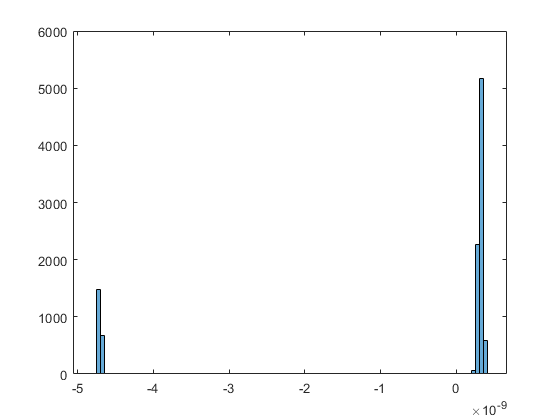

t_fino = (start)*tau_start - (stop)*tau_stop;
% t_fino = (start-stop)*tau_stop;
t = (coarse*T) + t_fino;
histogram(t_fino, 100)   

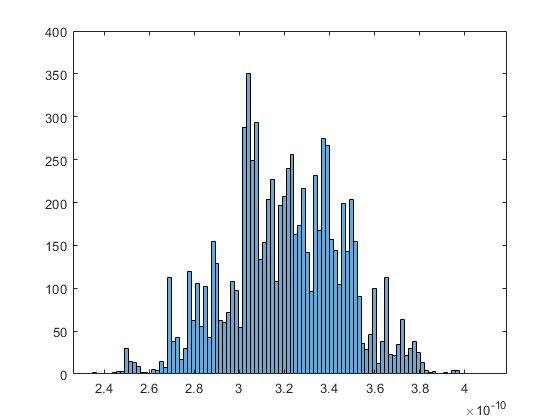

histogram(t_fino(t_fino>0), 100)

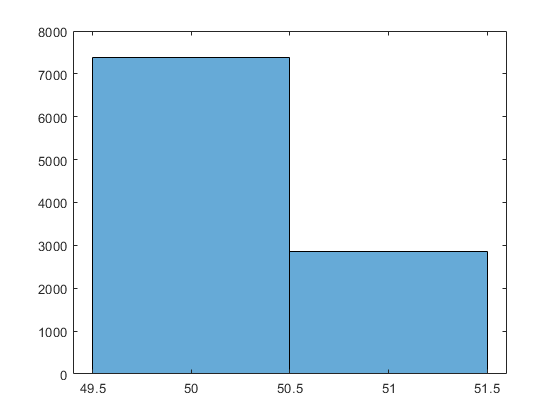

histogram(coarse)

sprintf('50 coarse son: %d y lo buscado es: %d', 50*T, T_buscado)

ans = '50 coarse son: 2.500000e-07 y lo buscado es: 2.500000e-07'

indices_50 = find(coarse==50);
indices_51 = find(coarse==51);

st = start-stop

st =     14
    14
    14
    14
    14
    14
    14
    14
    14
    14


st_positivo = st(st>0);
std(st_positivo)

ans = 2.4107

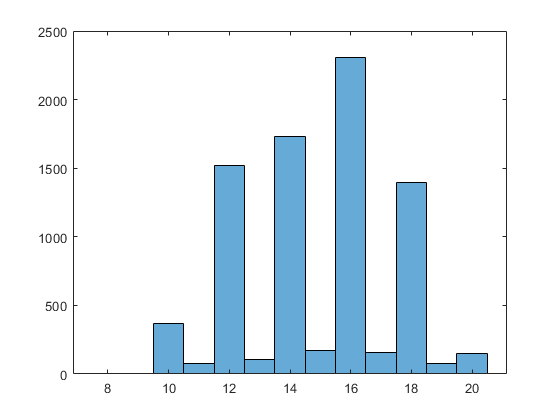

histogram(st(st>0))

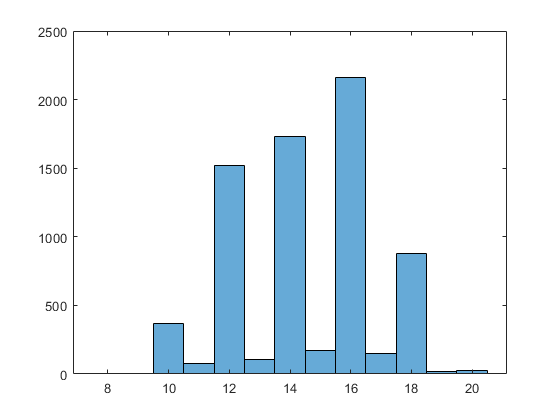


%Mediciones 50
clf;
fino_50 = t_fino(indices_50);
coarse_50 = coarse(indices_50);
celdas = start(indices_50)-stop(indices_50);
histogram(celdas(celdas>0))

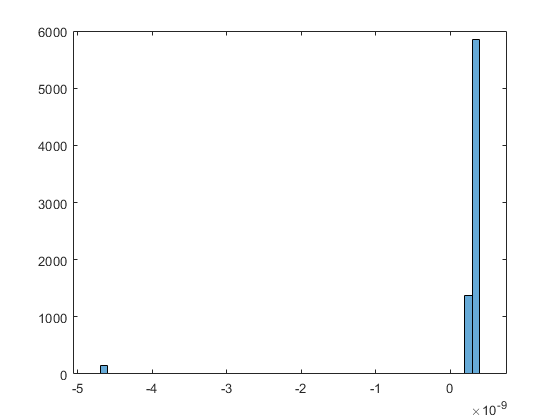

histogram(fino_50);

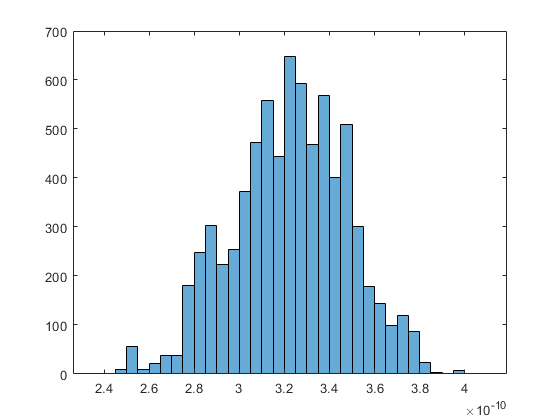

fino_50_buenas = fino_50(fino_50>0);
coarse_50_buenas = coarse_50(fino_50>0);
fino_50_malas = fino_50(fino_50<0);
coarse_50_malas = coarse_50(fino_50<0);
histogram([fino_50_buenas; fino_50_malas+T])

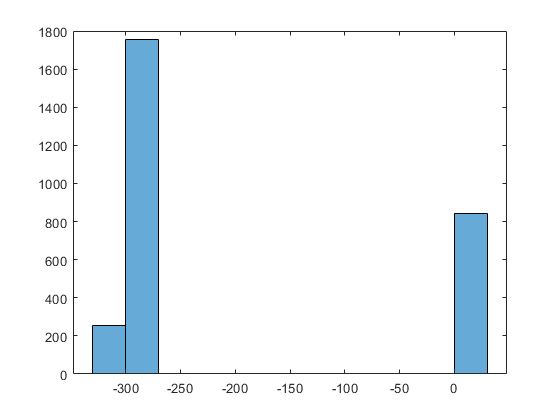



%%Mediciones 51
clf;
histogram(start(indices_51)-stop(indices_51))

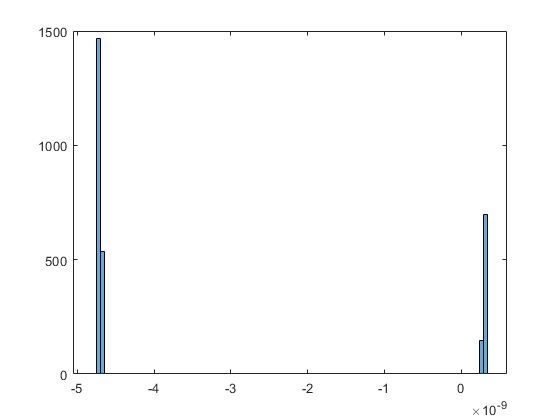

fino_51 = t_fino(indices_51);
coarse_51 = coarse(indices_51);
histogram(fino_51, 100)

st = start-stop

st =      6
     8
     8
     8
     6
     8
     8
     6
     6
     8


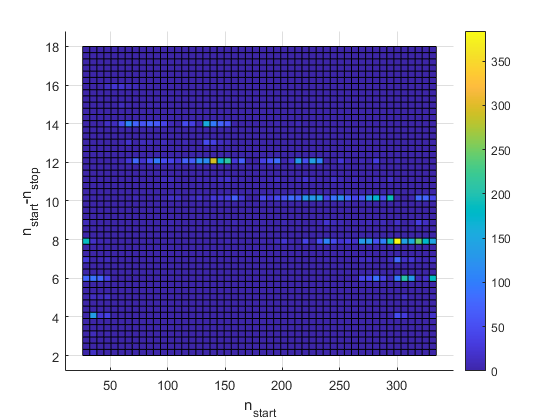

indices_st_pos = find(st>0);
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (n_max_start-n_min_start);
% std(st_positivo)
hist3([start, st], 'CdataMode','auto', 'Nbins', [50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_2M.eps');

#### Export

clf;
y = [fino_50_malas+T; fino_50_buenas; fino_51];
presicion = std(y)

presicion = 4.6200e-11

media     = mean(y)

media = 1.6552e-10

coarse_correcto = 50;
N = 100;
% Clear figure
clf;

% Data vectors
data = {fino_51, fino_50_malas+T, fino_50_buenas};

% Number of bins
N = 100;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = linspace(min_val, max_val, N+1);

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end
length(fino_51)

ans = 796

length(fino_50_malas)

ans = 822

length(fino_50_buenas)

ans = 8622

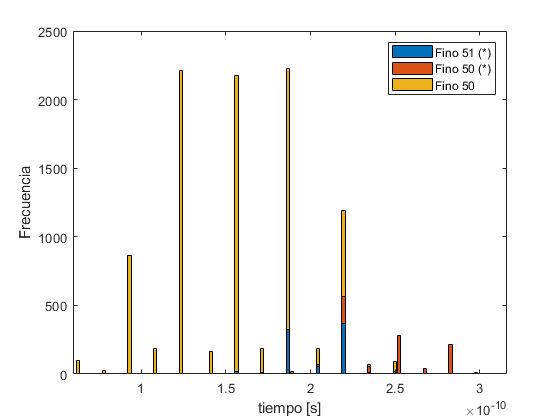

% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo [s]');
ylabel('Frecuencia');
legend({['Fino 51 (*)'], 'Fino 50 (*)', 'Fino 50'});
exportgraphics(gcf,'histograma_2M.eps');




format long
T_buscado

T_buscado =      2.500000000000000e-07


Tiempo_final = 50*T + media

Tiempo_final =      2.501655226679687e-07


error = Tiempo_final - T_buscado

error =      1.655226679687424e-10


clf;
% Clear figure
clf;

% Data vectors
data = {coarse_51, coarse_50_malas, coarse_50_buenas};

% Number of bins
N = 8;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = 49.5:0.25:51.5

commonEdges =   49.500000000000000  49.750000000000000  50.000000000000000  50.250000000000000  50.500000000000000  50.750000000000000  51.000000000000000  51.250000000000000  51.500000000000000


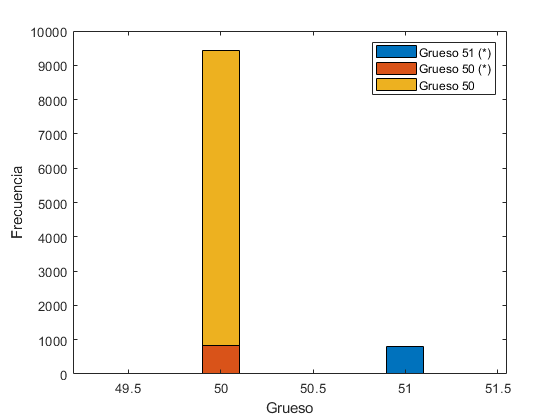


% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('Grueso');
ylabel('Frecuencia');
legend({['Grueso 51 (*)'], 'Grueso 50 (*)', 'Grueso 50'});
exportgraphics(gcf,'histograma_coarse_2M.eps');

% clear;
% data = load('resultadosCSV_2m_7.txt');
% 
% stop    = data(:, 1);
% start   = data(:, 2);
% coarse  = data(:, 3);
% 
% tau_stop    = 15.72e-12;
% n_min_stop  = 35;
% n_max_stop  = 353;
% tau_start   = 16.23e-12;
% n_min_start = 27
% n_max_start = 335
% T           = 5e-9;
% 
% T_buscado = 1/(2*2e6)

% t_fino = (start)*tau_start - (stop)*tau_stop;
% t = (coarse*T) + t_fino;
% histogram(t_fino)
% histogram(coarse)
% 
% sprintf('50 coarse son: %d y lo buscado es: %d', 50*T, T_buscado)
% indices_50 = find(coarse==50);
% indices_51 = find(coarse==51);
% 
% x = 1:1:1024
% plot(x, start);
% hold on;
% plot(x, stop);
% plot(x, 50*(coarse-50)+200)
% hold off;
% 
% 50*T
% %Mediciones 50
% clf;
% fino_50 = t_fino(indices_50);
% fino_50_buenas = fino_50(fino_50>0);
% histogram(fino_50_buenas);